# Power-Split HEV Model

mdl = "PowerSplitHEV_system_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

imageSaveFolder = fullfile( currentProject().RootFolder, "HEV", "images" );

% Load parameters
PowerSplitHEV_params

## Longitudinal Vehicle

Resisting Force and Power

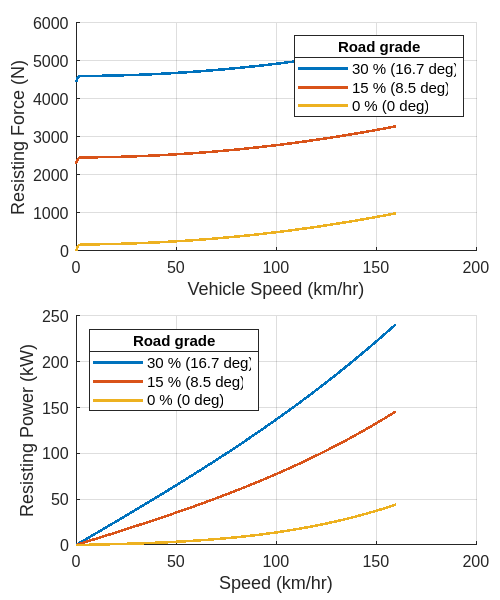

% Set referenced subsystem
set_param( mdl + "/Longitudinal Vehicle", ...
  "ReferencedSubsystem", "Vehicle1D_refsub_Basic")

% Select subsystem
set_param(0, "CurrentSystem", mdl+"/Longitudinal Vehicle")

% Select block and collect block parameters
set_param(gcs, "CurrentBlock", "Longitudinal Vehicle")

%{
block_info = Vehicle1DUtility.getVehicle1DDrivelineBlockInfo(gcbh);
fig = Vehicle1DUtility.plotRoadLoad( ...
  "VehicleMass_kg", block_info.M_e_kg, ...
  "RoadLoadA_N", block_info.A_rl_N, ...
  "RoadLoadB_N_per_kph", block_info.B_rl_N_per_kph, ...
  "RoadLoadC_N_per_kph2", block_info.C_rl_N_per_kph2, ...
  "GravitationalAcceleration_m_per_s2", block_info.grav_m_per_s2, ...
  "VehicleSpeedVector_kph", linspace(0, 160, 200), ...
  "RoadGradeVector_pct", [30, 15, 0] );
%}

sdlTmpInfo = sdlUtility.getLongitudinalVehicleInfo(gcbh);

fig = sdlUtility.plotLongitudinalVehicleResistance( ...
  VehicleMass = sdlTmpInfo.VehicleMass, ...
  RoadLoadA = sdlTmpInfo.RoadLoadA, ...
  RoadLoadB = sdlTmpInfo.RoadLoadB, ...
  RoadLoadC = sdlTmpInfo.RoadLoadC, ...
  GravitationalAcceleration = sdlTmpInfo.GravitationalAcceleration, ...
  VehicleSpeedThreshold = sdlTmpInfo.VehicleSpeedThreshold, ...
  VehicleSpeedVector = simscape.Value(linspace(0, 160, 200)', "km/hr"), ...
  VehicleSpeedPlotUnit = "km/hr", ...
  RoadGradeVector = [30, 15, 0] );

fig.Position(3:4) = [500 600];  % width height

imgPath = fullfile( imageSaveFolder, "image_Vehicle_ResistingForcePower.png");

exportgraphics(fig, imgPath)

## Engine

Torque and Power Curves at Wide Open Throttle

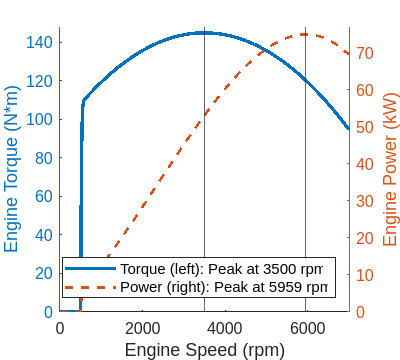

% Set referenced subsystem
set_param( mdl + "/Power Split Drive Unit/Engine", ...
  "ReferencedSubsystem", "Engine_refsub_Basic")

% Select subsystem
set_param(0, "CurrentSystem", mdl+"/Power Split Drive Unit/Engine")

% Select block and collect block parameters
set_param(gcs, "CurrentBlock", "Generic Engine")

sdlTmpInfo = sdlUtility.getGenericEngineInfo(gcb);

fig = sdlUtility.plotPolynomialEngineCurves( ...
  MaximumTorque = sdlTmpInfo.MaximumTorque, ...
  SpeedAtMaximumTorque = sdlTmpInfo.SpeedAtMaximumTorque, ...
  MaximumPower = sdlTmpInfo.MaximumPower, ...
  SpeedAtMaximumPower = sdlTmpInfo.SpeedAtMaximumPower, ...
  MaximumSpeed = sdlTmpInfo.MaximumSpeed, ...
  StallSpeed = sdlTmpInfo.StallSpeed, ...
  StallSpeedThreshold = sdlTmpInfo.StallSpeedThreshold );

imgPath = fullfile( imageSaveFolder, "image_Engine_TorquePower.png");

exportgraphics(fig, imgPath)

*Copyright 2022-2023 The Mathworks, Inc.*